addpath(fullfile("Models","siamese_vggface"));

datasetFolder = fullfile("FaceDatabase","lfw-funneled-scaled");
dataDetailsFolder = fullfile("Proprocessing","lfw-details");

% peopleGT2IMG_file = fullfile(dataDetailsFolder,"peopleGT2Images.csv"); % list of people greater or equal to 2 images

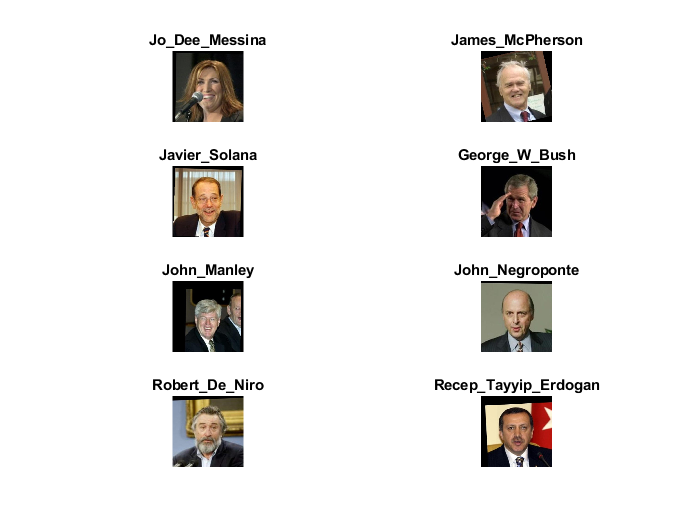

imdsTrain = imageDatastore(datasetFolder, ...
    "IncludeSubfolders",true, ...
    "LabelSource","foldernames");

% show random images
idx = randperm(numel(imdsTrain.Files),8);
for i = 1:numel(idx)
    subplot(4,2,i)
    imshow(readimage(imdsTrain,idx(i)))
    title(imdsTrain.Labels(idx(i)),"Interpreter","none");
end

% THIS WAS BEING USED FOR FILTERING PEOPLE WITH MORE THAN 2 IMAGES, BUT
% SUPERCEEDED BY EXTRA IMIPLEMENTATION WITHIN getSimilarPair
% this problem need to be solved as some subject only has a single image
% that cannot be used to generate similar pair

% if ~exist(peopleGT2IMG_file, "file")
%     addpath("Proprocessing");
%     tb = readPeopleText(fullfile(dataDetailsFolder,"people.txt"));
%     writetable(tb(tb.instance > 1, :),fullfile(dataDetailsFolder,"peopleGT2Images.csv"));
% end
% peopleGT2IMG_table = readtable(peopleGT2IMG_file);
% peopleGT2IMG_table

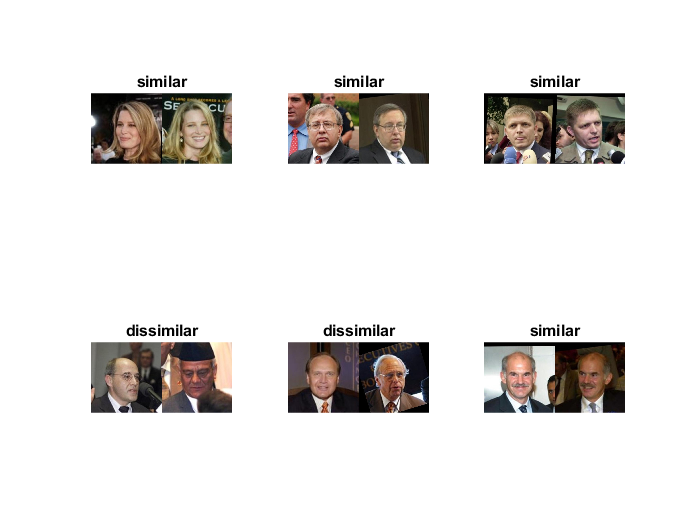

% generate pairs of images

batchSize = 6;
[pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize);
figure;
for i = 1:batchSize
    if pairLabel(i) == 1
        s = "similar";
    else
        s = "dissimilar";
    end
    subplot(2,3,i)
    imshow([pairImage1(:,:,:,i)/255 pairImage2(:,:,:,i)/255]);
    title(s)
end